# Get Started with Solver-Based Optimize Live Editor Task

This example script helps you to use the solver-based **Optimize** Live Editor task for optimization or equation solving. Modify the script for your own problem.

The script solves a nonlinear optimization problem with nonlinear constraints.

## Include Parameters or Data

Typically, you have data or values to pass to the solver. Place those values in the input section (where you see `x0`) and run the section by choosing **Section > Run Section** or pressing `Control+Enter`.

Set the initial point `x0` and scale `a` for the optimization.

%x(1) = kp; x(2) = kd; x(3) = ki;
x0 = [0.0001; 0.0001; 0.0001];
x = x0;

%a(1) = os; a(2) = ts;
a = [2, 3];

nvar = 3;

**Place the **`x0`** value and any other problem data into the workspace** by running this section before proceeding.

%{
ideal = [3.736673e-4, 1.163698e-4, 6.884364e-3];

mdl = 'GA_pendulo';
load_system(mdl);

set_param(mdl, 'StopTime', num2str(1000));

% Set the PID parameters
pid_block = 'GA_pendulo/C2';

set_param(pid_block, 'P', num2str(ideal(1)), 'I', num2str(ideal(3)), 'D', num2str(ideal(2)));

simout = sim(mdl); % Simular o modelo
ta = simout.xout.Time; % Tempo da simulação
ya = simout.xout.Data; % Saída do sistema

a(1) = overshoot(ya); % Calcular o overshoot
a(2) = settling_time(ya, ta); % Calcular o tempo de acomodação
%}

## Optimize Live Editor Task

Usually, you place the Optimize Live Editor task into the script by selecting **Task > Optimize** in the **Live Editor** tab, or by selecting **Task > Optimize** in the **Insert** tab. Then you are presented with the following choice (this is only a picture, not the real task):

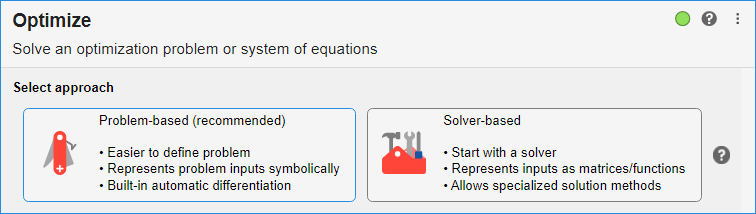

To get the solver-based task, click **Solver-based**.

The following solver-based task has objective and nonlinear constraint functions included. To change these functions, edit the function listings below the task.

To change the constraints, select appropriate constraint types and enter values in the input boxes. You might need to enter values in the section containing `x0` above, and run the section to put values in the workspace.

Run the task by clicking the striped bar to the left, or by choosing **Run** or **Section > Run Section**, or by pressing `Control+Enter`.


Single objective optimization:
3 Variable(s)
6 Nonlinear equality constraint(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                              Best       Max        Stall
Generation  Func-count        f(x)     Constraint  Generations
    0.0001    0.0586    0.0959

   10.4645

    0.0001    0.0586    0.0959

   10.4645

    0.0001    0.0586    0.0959

   10.4645

    1            128       10.4645       0.0999      0
    0.0001    0.0586    0.0959

   10.4645

    0.0001    0.0586    0.0959

   10.4645

    0.0001    0.0586    0.0959

   10.4645

    0.0001    0.0586    0.0959

   10.4645

    0.0001    0.0586    0.0959

   10.4645

    0.0001    0.0586    0.0959

   10.4645

    0.0001    0.0586    0.0959

   10.4645

    0.0001    0.0586    0.0959

   10.4645

    0.0001    0.0586    0.0959

   10.4645

    0.0001    0.0586    0.0959

   10.4645

  

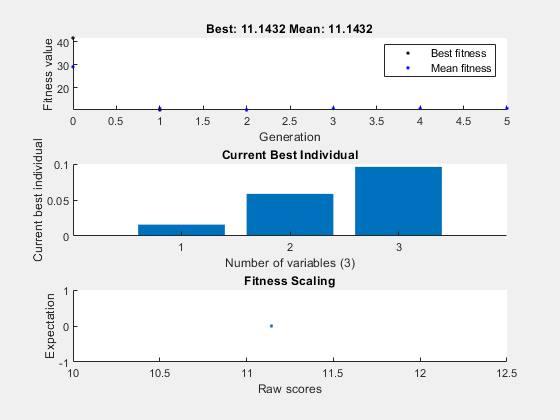

% Pass fixed parameters to objfun
objfun = @(x)objectiveFcn(x,a);

% Set nondefault solver options
options = optimoptions("ga","PopulationSize",20,"MaxGenerations",5,...
    "EliteCount",3,"Display","iter","PlotFcn",["gaplotbestf",...
    "gaplotbestindiv","gaplotexpectation"]);

% Solve
[solution2,objectiveValue2] = ga(objfun,nvar,[],[],[],[],repmat(0.0001,nvar,1),...
    repmat(0.1,nvar,1),@constraintFcn,[],options);


% Clear variables
clearvars objfun options


## Results

`Optimize` saves the solution to the workspace variable `solution`, and saves the objective function value at the solution to the workspace variable `objectiveValue`. You can see and modify these variable names at the top of the `Optimize` task.

View these variables.

solution2

solution2 =     0.0157    0.0586    0.0959


objectiveValue2

objectiveValue2 = 11.1432

View the nonlinear constraint function values at the solution.

[ccons,ceqcons] = constraintFcn(solution2)


ccons =

     []



ceqcons =    -0.0156    0.0843   -0.0585    0.0414   -0.0958    0.0041


## Helper Functions — Local Functions

The following code creates the objective function. Modify this code for your problem.

function f = objectiveFcn(x, a)
    mdl = 'GA_pendulo';
    load_system(mdl);

    set_param(mdl, 'StopTime', num2str(10/max(x)));

    % Set the PID parameters
    pid_block = 'GA_pendulo/C2';
    
    set_param(pid_block, 'P', num2str(x(1)), 'I', num2str(x(3)), 'D', num2str(x(2)));

    simout = sim(mdl); % Simular o modelo
    t = simout.xout.Time; % Tempo da simulação
    y = simout.xout.Data; % Saída do sistema
    
    os = overshoot(y); % Calcular o overshoot
    ts = settling_time(y, t); % Calcular o tempo de acomodação

    f = abs(a(1) - os(1))/a(1) + abs(a(2) - ts)/a(2);
    if f < 10.5
        disp(x);
        disp(f);
    end
    
end

function st = settling_time(xout, tr)
    final = xout(end);

    for i = length(xout):-1:1
        if xout(i) > 1.02*final || xout(i) < 0.98*final
            st = tr(i) - tr(1);
            break;
        end
    end
end

The following code creates the constraint function. Modify this code for your problem.

function [c,ceq] = constraintFcn(x)
    % Inequality constraints (empty in this case)
    c = [];
    
    
    % Equality constraints
    ceq(1) = 0.0001 - x(1);   % Lower bound for x(1): x(1) >= 0.0001
    ceq(2) = 0.1 - x(1);   % Upper bound for x(1): x(1) <= 0.1
    ceq(3) = 0.0001 - x(2);   % Lower bound for x(2): x(2) >= 0.0001
    ceq(4) = 0.1 - x(2);   % Upper bound for x(2): x(2) <= 0.1
    ceq(5) = 0.0001 - x(3);   % Lower bound for x(3): x(3) >= 0.0001
    ceq(6) = 0.1 - x(3);   % Upper bound for x(3): x(3) <= 0.1
end

*Copyright 2020 The MathWorks, Inc.*